% 本文件中使用链表存储生物体来进行无地理关系的随机博弈，故为list.mlx
clear;close all;clc;
set(0, 'RecursionLimit', 1000)

% 博弈的参数
profit = [ 18,18; -5,-5 ; 20,-10 ; -10,20 ]; % 收益矩阵：第一组是都合作的收益，第二组是都竞争的收益，第三组是A竞争、B合作的收益，第四组是A合作、B竞争的收益
round_num = 35;

% A种群的参数
resourceA = 100;
max_resA = 300;
lifespanA = 30;
op_probA = 0.8;
A_initnum = 10; % 初始指定的种群数量

% B种群的参数
resourceB = 100;
max_resB = 300;
lifespanB = 30;
op_probB = 0.6;
B_initnum = 10;

% C种群的参数
resourceC = 100;
max_resC = 300;
lifespanC = 30;
op_probC = 0.4;
C_initnum = 10;

% 建立初始的生物体链表

% o_A = Organism("A",resourceA,max_resA,lifespanA,op_probA); % 用于初始化链表的第一个生物
% org_A = LinkedList(o_A);
% for i = 1:(A_initnum-1)
%     o = Organism("A",resourceA,max_resA,lifespanA,op_probA);
%     org_A.append(o);
% end

o_B = Organism("B",resourceB,max_resB,lifespanB,op_probB);
org_B = LinkedList(o_B);
for i = 1:(B_initnum-1)
    o = Organism("B",resourceB,max_resB,lifespanB,op_probB);
    org_B.append(o);
end

o_C = Organism("C",resourceC,max_resC,lifespanC,op_probC);
org_C = LinkedList(o_C);
for i = 1:(C_initnum-1)
    o = Organism("C",resourceC,max_resC,lifespanC,op_probC);
    org_C.append(o);
end

% org_A.merge(org_B,[],org_C);
org_B.merge(org_C)

% 博弈
g = Game(profit,round_num);
% [kind_map_array,org_A,end_round] = g.play_list(org_A);
[kind_map_array,org_B,end_round] = g.play_list(org_B);
if end_round < round_num
    disp("由于总生物数量超过10000，博弈结束于第"+num2str(end_round)+"轮")
end

% 博弈结果输出
kind_map_1 = kind_map_array{1};
kind = string(keys(kind_map_1)); % 获取所有键（种类）
kind_num = length(kind); % 获取种类的个数

amount_mat = zeros(kind_num); % 新建一个存储种群数量的矩阵，第i列对应第i个种群（键）
for i = 1:length(kind_map_array)
    kind_map = kind_map_array{i};
    amount = [];
    for j = 1:kind_num
        a = kind_map(kind(j)); % 获取所有值（每轮迭代各种群的数量），并将其转换为数组
        amount = [amount,a];
    end
    amount_mat = [amount_mat;amount];
end
amount_mat = amount_mat(kind_num+1:end, :); % 删除初始化的全零行

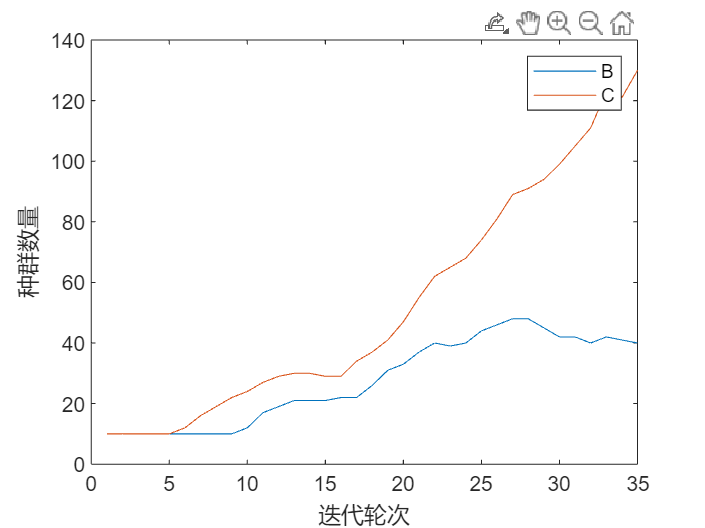

% 绘图
x = 1:round_num;
for i = 1:kind_num
    y = amount_mat(:,i); % 取出每一列（各种群的数量）
    y = y';
    plot(x,y)
    hold on
end
xlabel("迭代轮次")
ylabel("种群数量")
legend(kind(1),kind(2))